loding data

clear

Path = {    'DeepLearningData/Normal/M',...
             'DeepLearningData/Normal/T'};
 imds = imageDatastore(Path,'IncludeSubfolders',true,'LabelSource','foldernames');
 

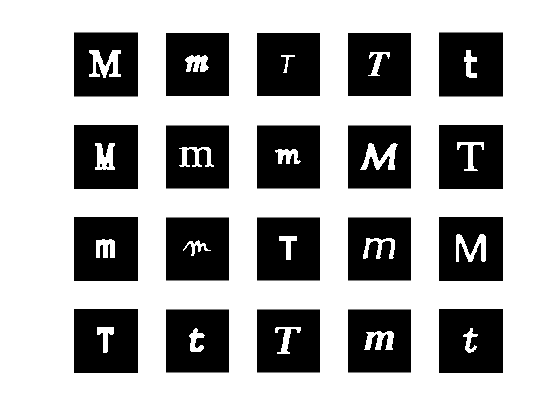

  figure;
        perm = randperm(length(imds.Files),20);
        for i = 1:20
            subplot(4,5,i);
            imshow(imds.Files{perm(i)});
        end

        labelCount = countEachLabel(imds)   

labelCount = 2×2 table
    Label    Count
    _____    _____

      M       600 
      T       600 


  numTrainFiles = 400;
  [imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');
  

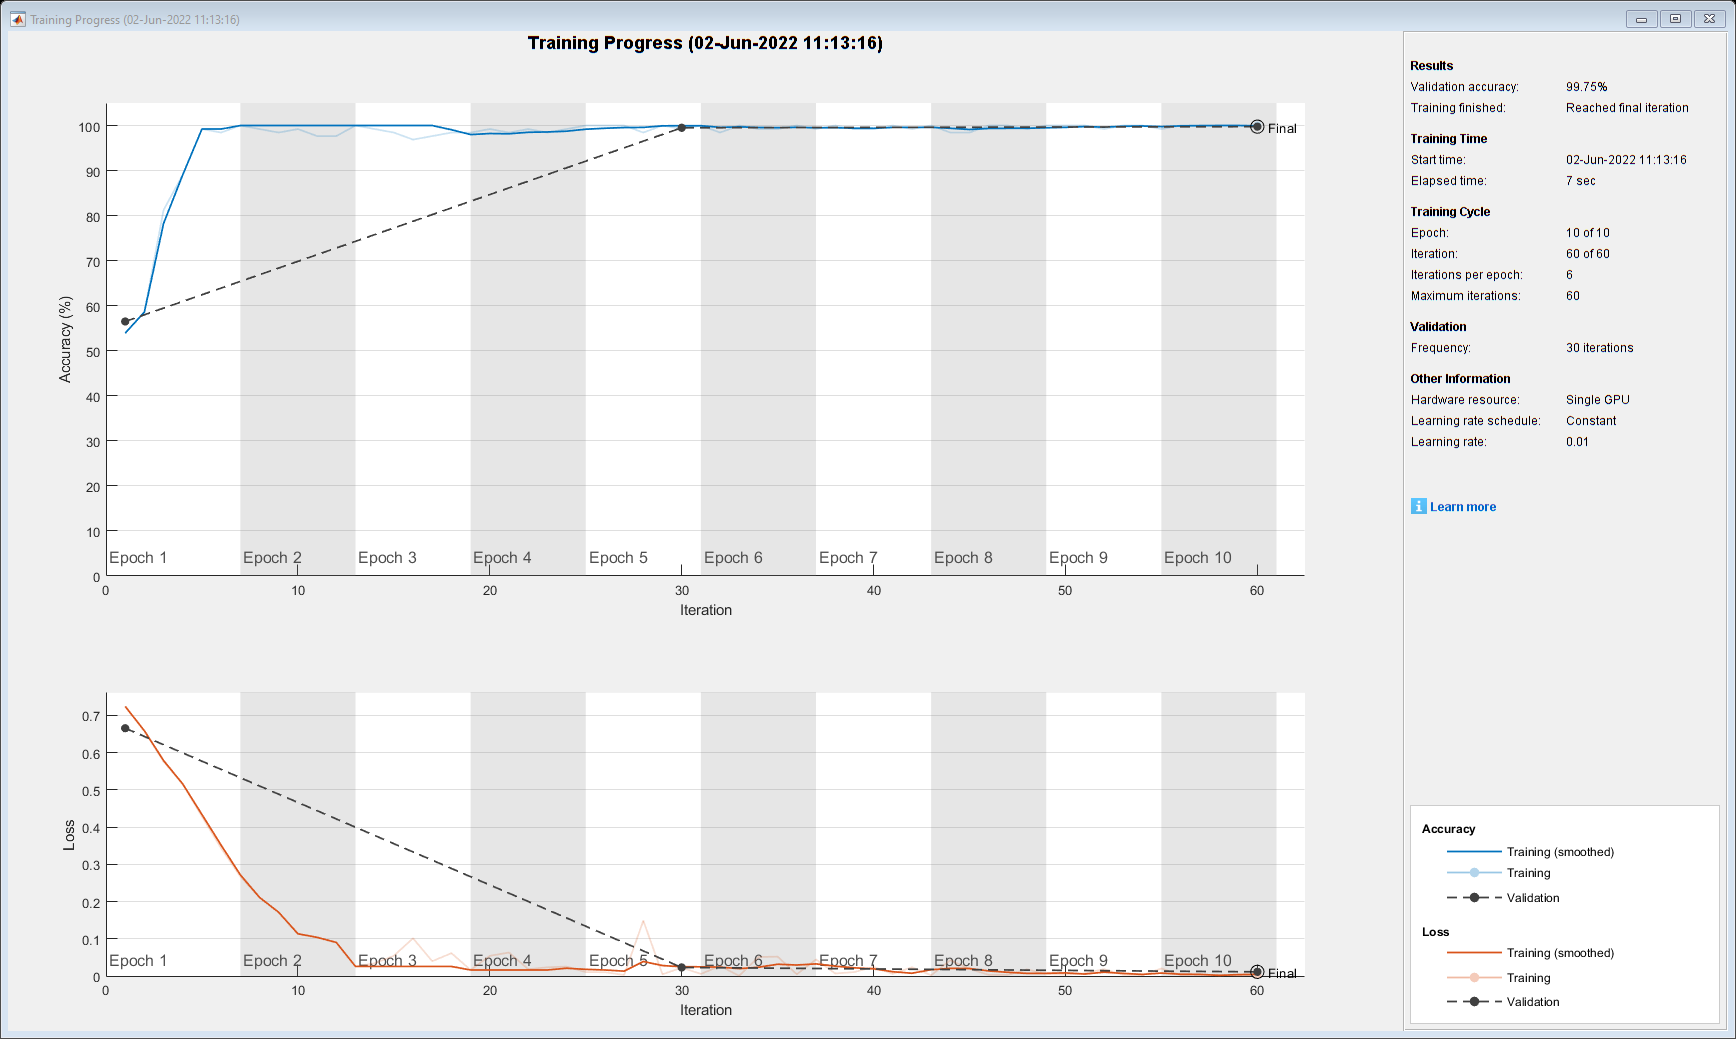

% imageInputLayer([150 150 1]) 
% 
% convolution2dLayer(3,8,'Padding','same')
% batchNormalizationLayer
% reluLayer
% maxPooling2dLayer(2,'Stride',2)


layers = [
imageInputLayer([150 150 1])
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(2)
softmaxLayer
classificationLayer];

options = trainingOptions('sgdm', ...
'InitialLearnRate',0.01, ...
'MaxEpochs',10, ...
'Shuffle','every-epoch', ...
'ValidationData',imdsValidation, ...
'ValidationFrequency',30, ...
'Verbose',false, ...
'Plots','training-progress');

net = trainNetwork(imdsTrain,layers,options);